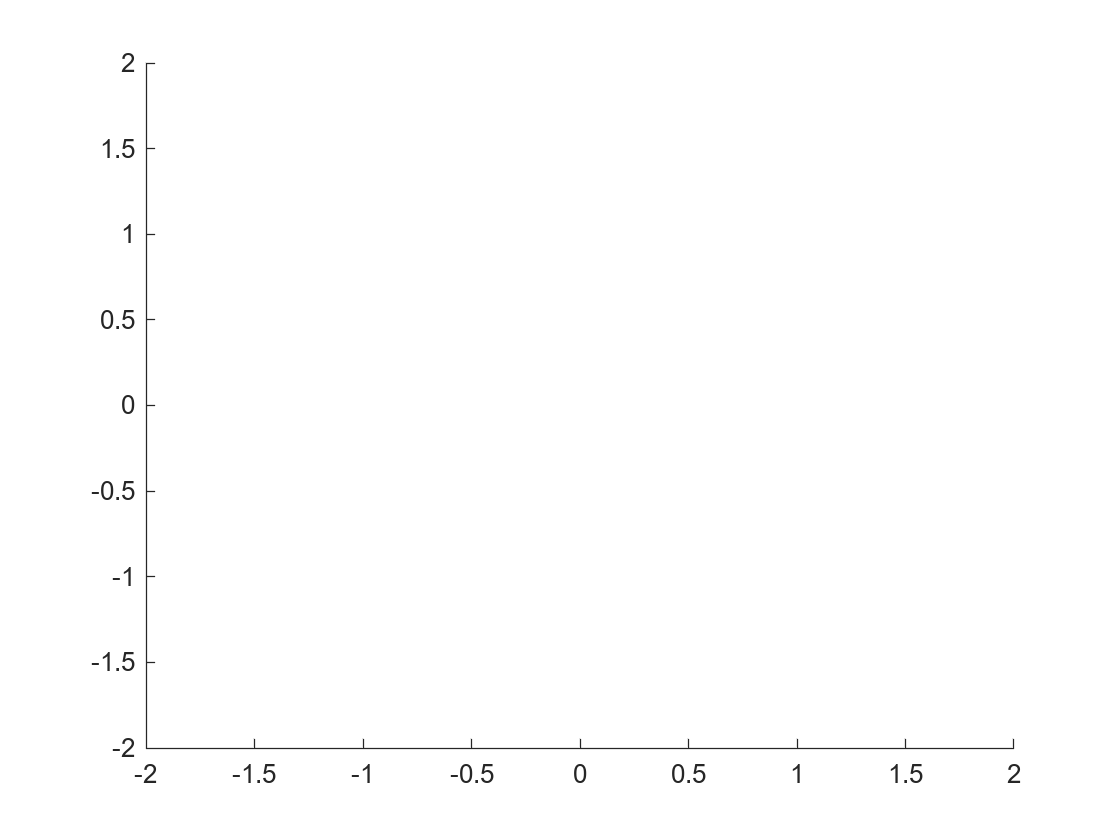

ke = 0.4987;
km = ke; 
R =  8.8696;
L = 0.0047;
J = 0.0023;
goal_x=-1;
goal_y=0;
r=0.028;
B=0.21;

h=2;
xlim([-h h]);
ylim([-h h]);

K_r = 0.5000

K_s = 0.5000

simout =   Simulink.SimulationOutput:

                      V: [1x1 timeseries] 
                   tout: [133x1 double] 
                      x: [1x1 timeseries] 
                      y: [1x1 timeseries] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


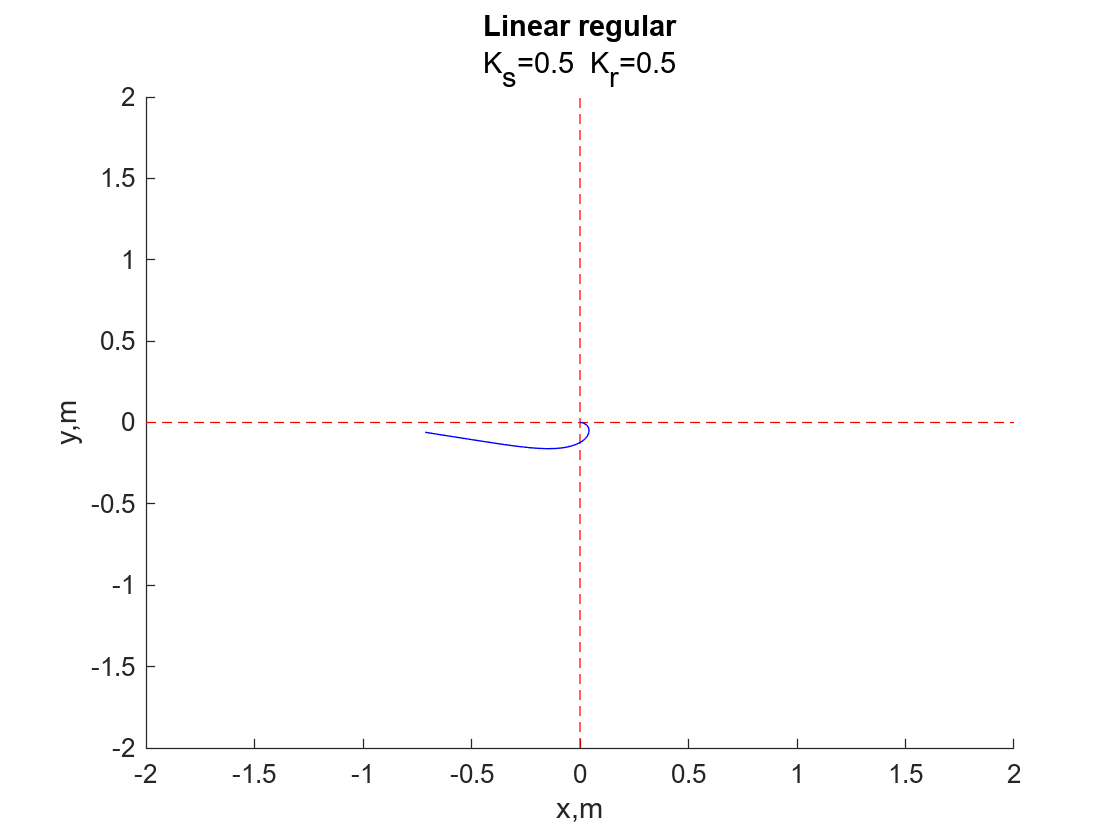

K_r = 1

K_s = 1

simout =   Simulink.SimulationOutput:

                      V: [1x1 timeseries] 
                   tout: [28258x1 double] 
                      x: [1x1 timeseries] 
                      y: [1x1 timeseries] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


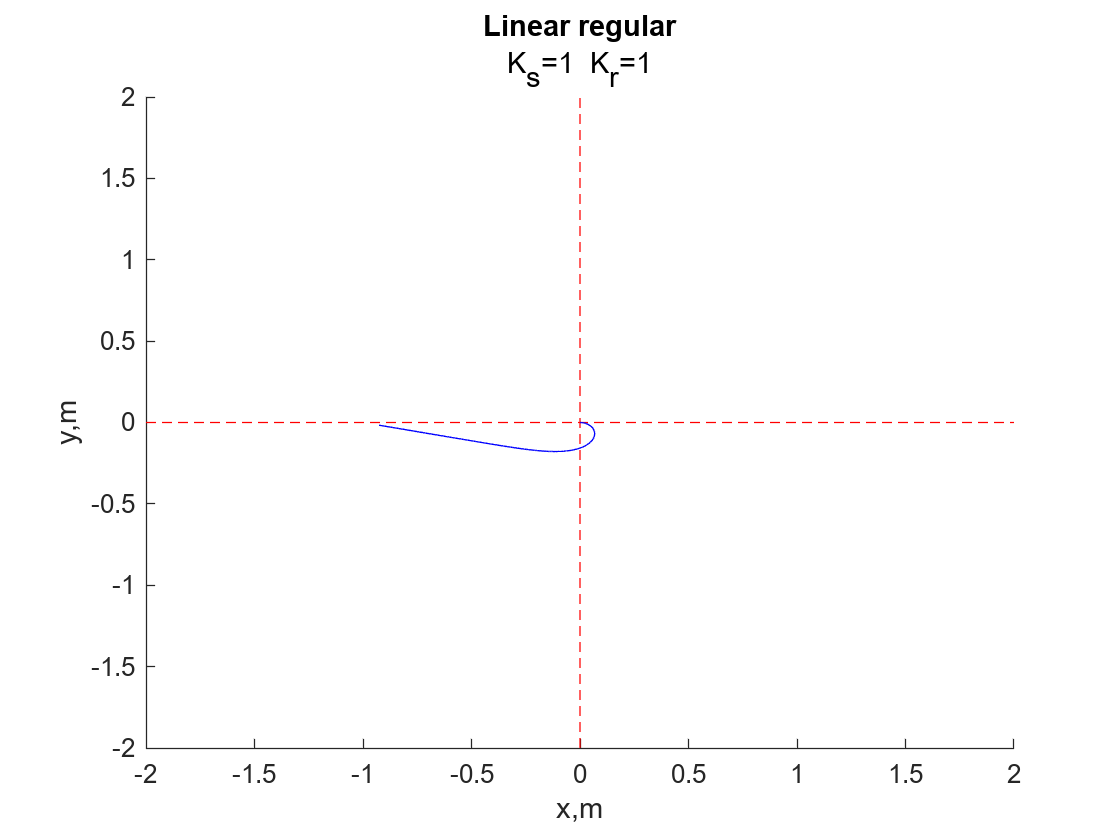

K_r = 5

K_s = 5

simout =   Simulink.SimulationOutput:

                      V: [1x1 timeseries] 
                   tout: [28263x1 double] 
                      x: [1x1 timeseries] 
                      y: [1x1 timeseries] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


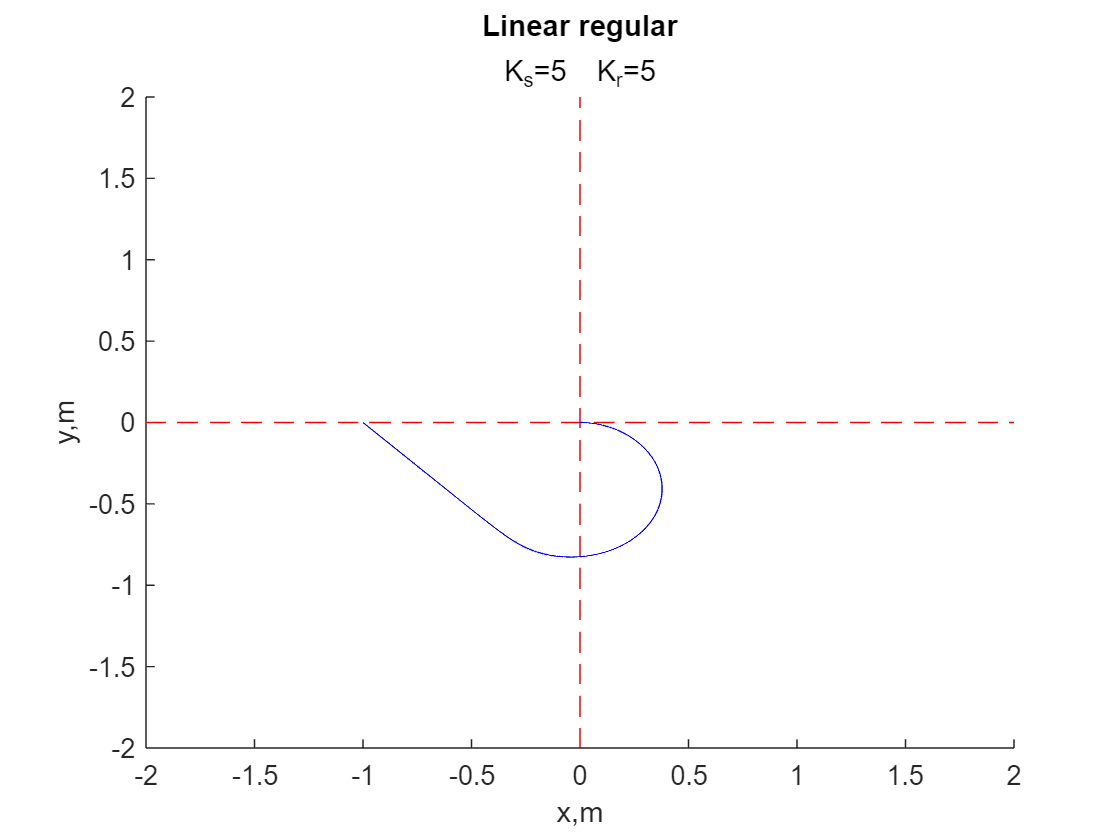

for i=[0.5 1 5]
    K_r=i
    K_s=i
    figure(i*10)
    simout=sim('VPD_lab_4_linear.slx')
    hold on;
    plot([-h, h], [0, 0], 'r--')
    plot([0, 0], [-h, h], 'r--')
    plot(simout.x.Data, simout.y.Data,'b')
    hold off;
    h2 = strcat('K_s=',string(K_s),'  K_r=', string(K_r));
    title('Linear regular',h2)
    xlabel('x,m');         
    ylabel('y,m');
end

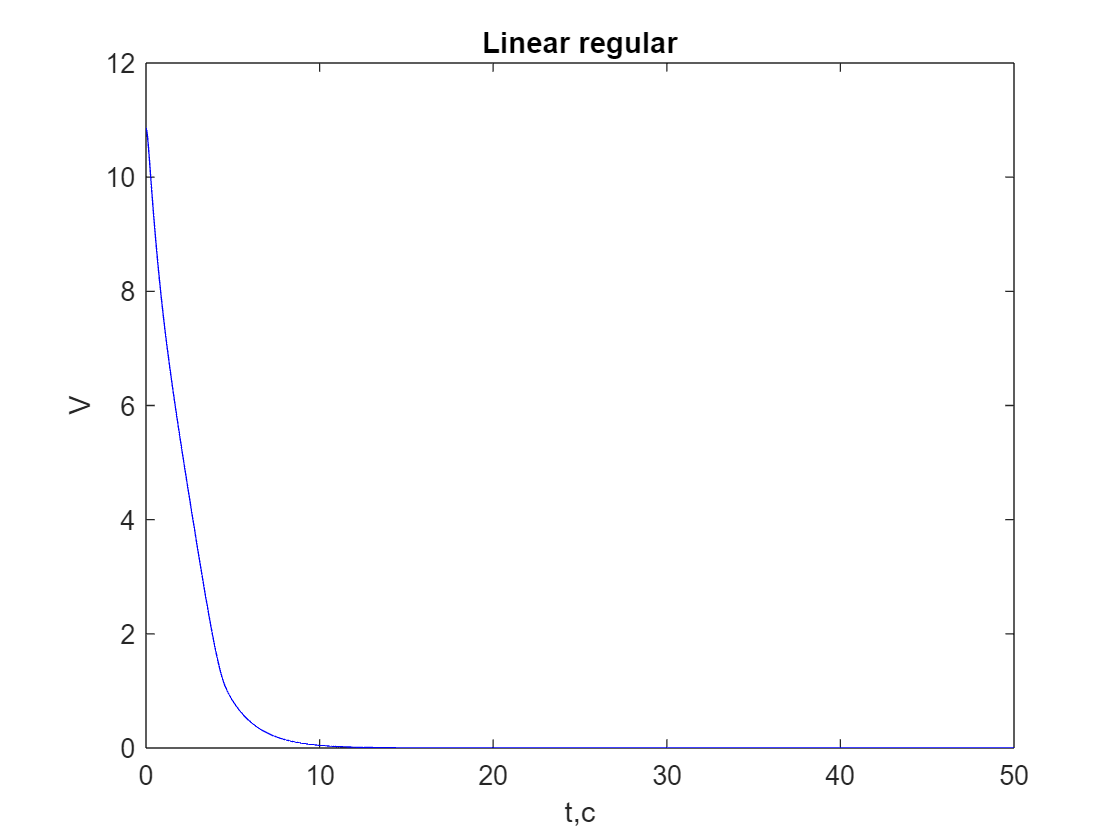

plot(simout.V.Time, simout.V.Data,'b')
xlabel('t,c');
ylabel('V');
title('Linear regular')